## Common 2-D Plot

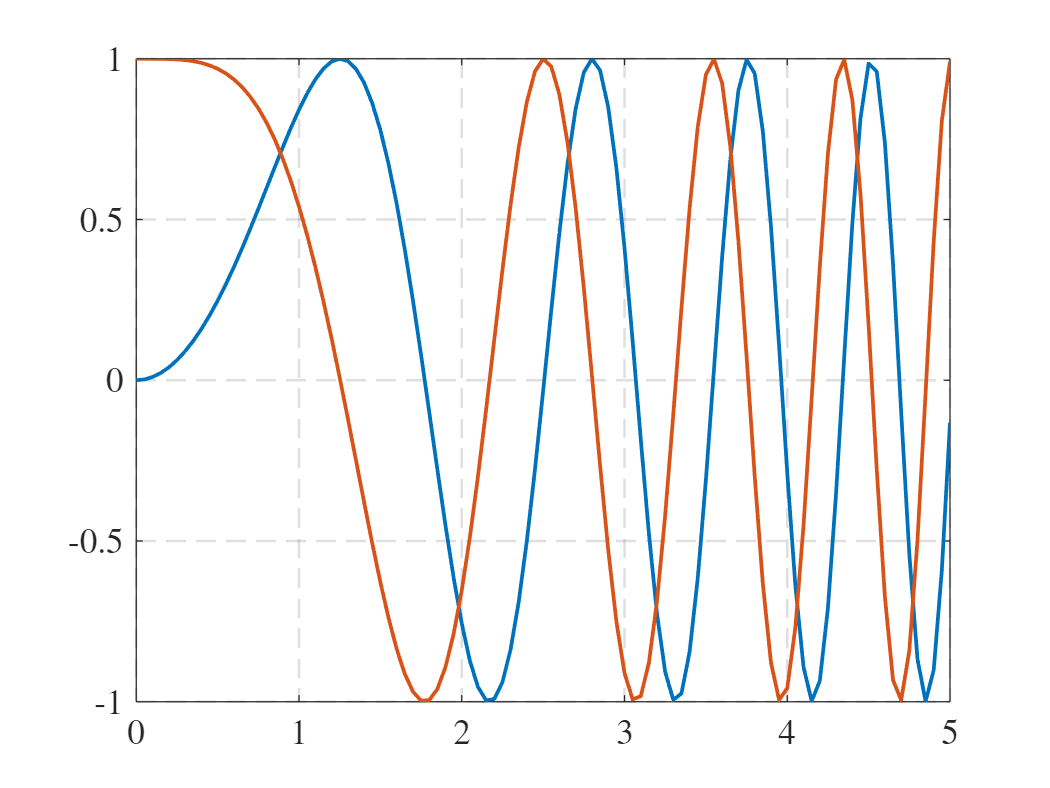

x= 0:0.05:5;
y1 = sin(x.^2);
y2 = cos(x.^2);
figure()
plot(x,y1,x,y2)

xlabel('x')
ylabel('sin(x)')
title('Plot of the Sine and Cosine Function')

## Plot With Table

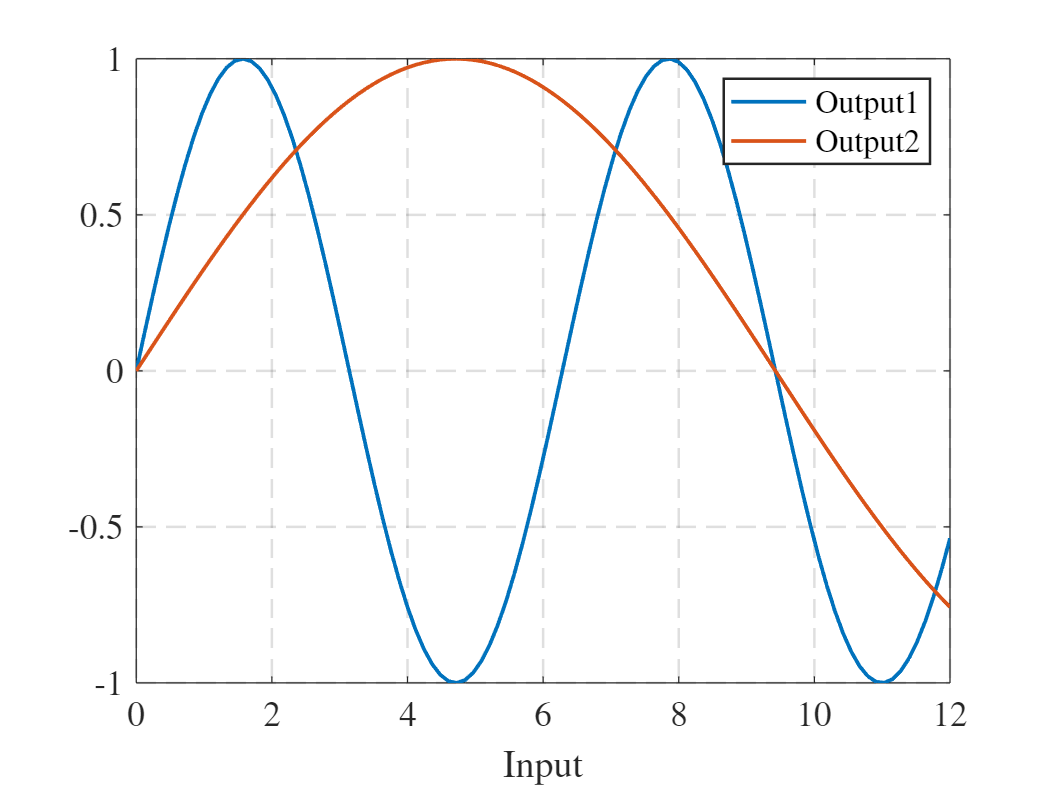

Input = linspace(0,12)';
Output1 = sin(Input);
Output2 = sin(Input/3);
tbl = table(Input,Output1,Output2);
plot(tbl,"Input",["Output1","Output2"])
legend

## Errorbar Plot

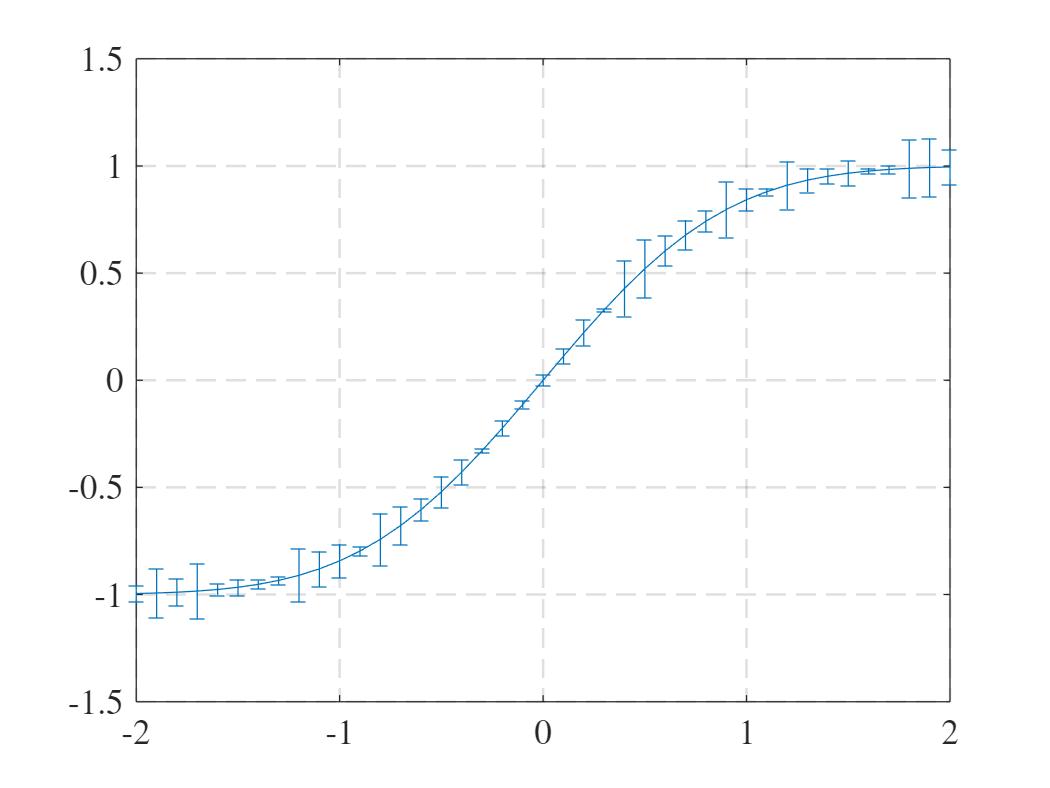

x = -2:0.1:2;
y = erf(x);
eb = rand(size(x))/7;
errorbar(x,y,eb)

## Stem Plot

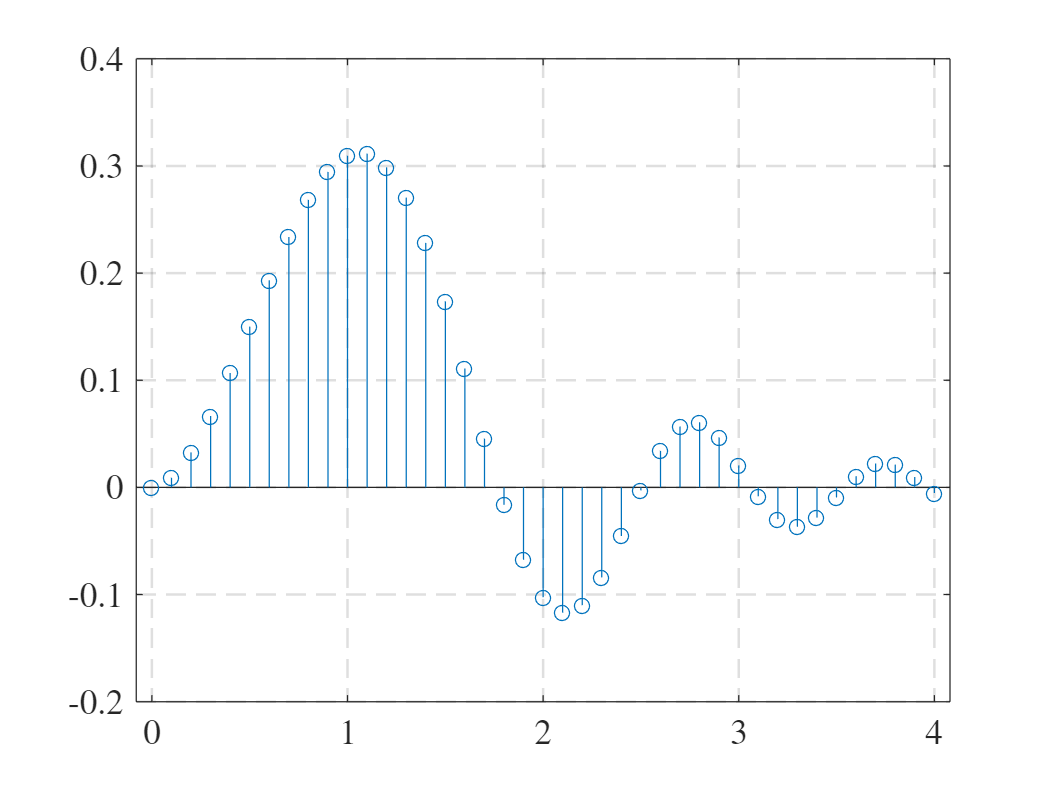

x = 0:0.1:4;
y = sin(x.^2).*exp(-x);
stem(x,y)

## Scatter Plot

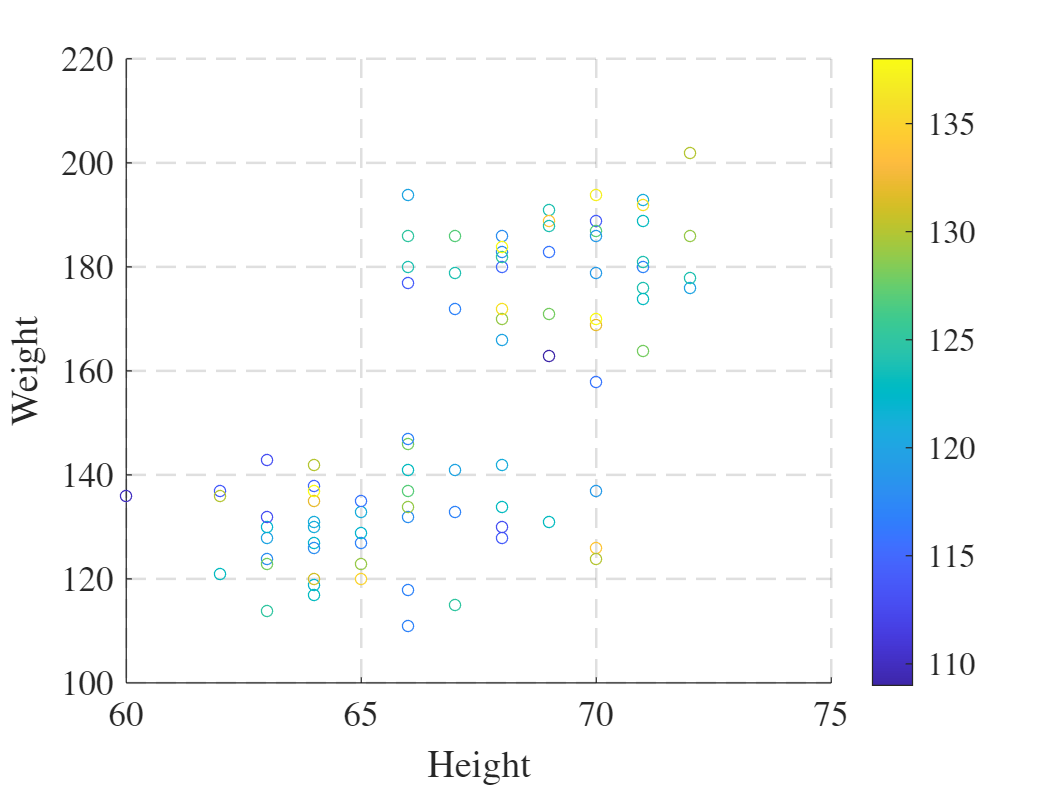

load patients.mat Height Weight Systolic
scatter(Height,Weight,20,Systolic)
xlabel('Height')
ylabel('Weight')
colorbar

## Combine Line and Bar Charts Using Two y-Axes

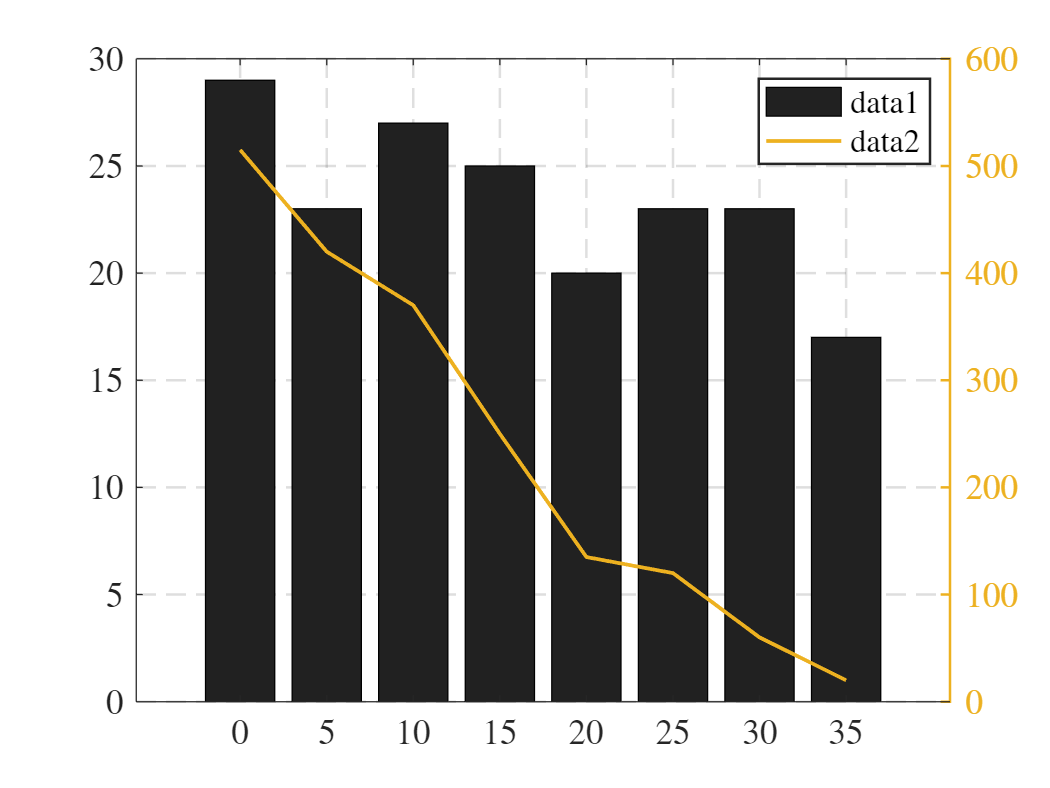

days = 0:5:35;
conc = [515 420 370 250 135 120 60 20];
temp = [29 23 27 25 20 23 23 17];

yyaxis left
b = bar(days,temp);

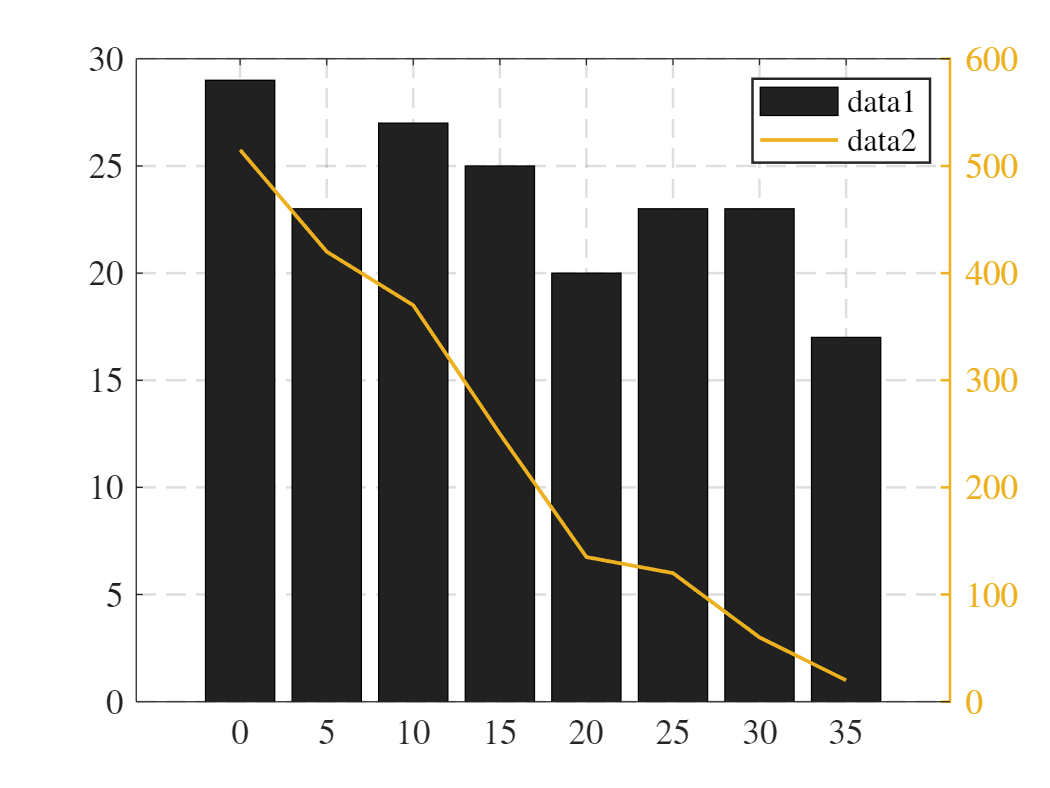


yyaxis right
p = plot(days,conc);

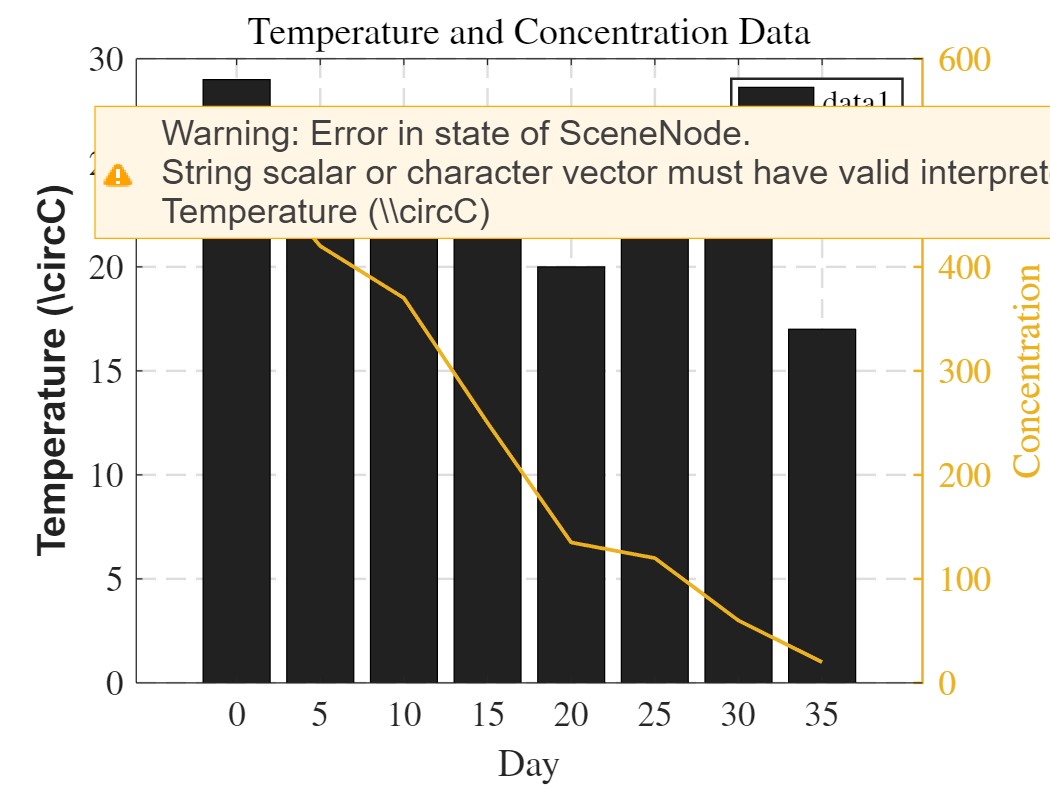


title('Temperature and Concentration Data')
xlabel('Day')
yyaxis left
ylabel('Temperature (\circC)')
yyaxis right
ylabel('Concentration')

## Line Plot with Confidence Bounds

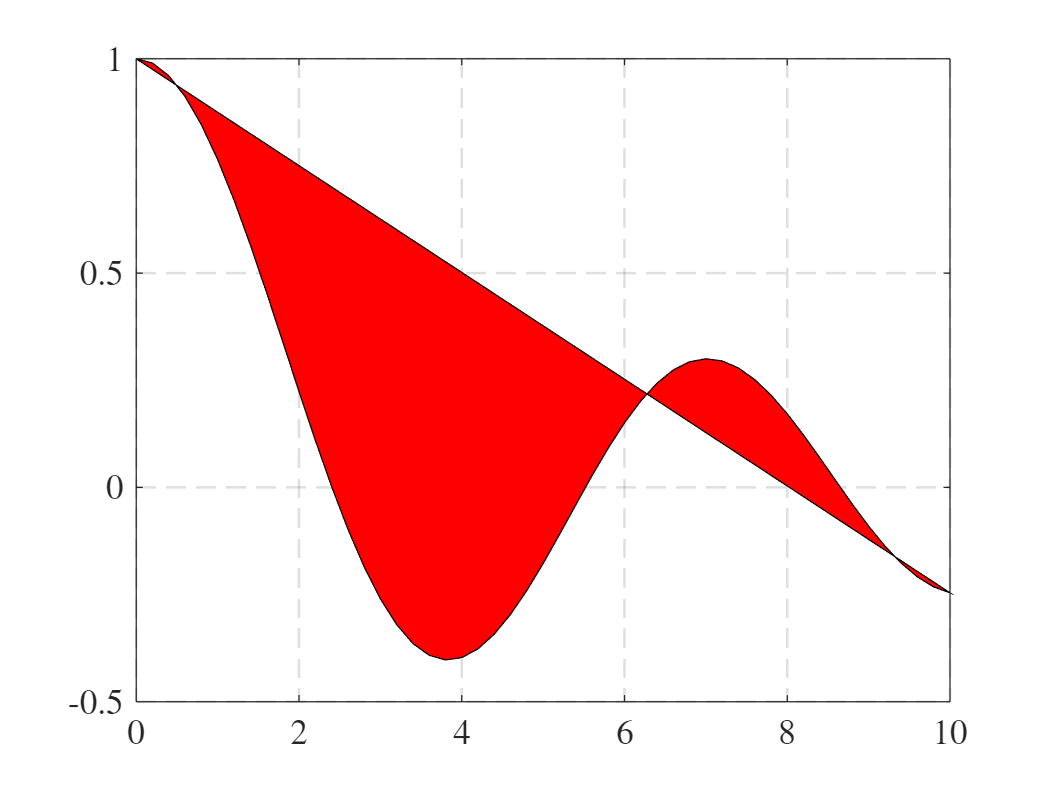

x = 0:0.2:10;
y = besselj(0, x);

xconf = [x x(end:-1:1)] ; 
yconf = [y+0.15 y(end:-1:1)-0.15];

figure
p = fill(xconf,yconf,'red');

p.FaceColor = [1 0.8 0.8];
p.EdgeColor = 'none';

hold on
plot(x,y,'ro')
hold off

## Violin Plot

chip_yield = [0.8 + 0.1*randn(100,1),0.7+0.2*randn(100,1),0.6+0.3*rand(100,1)];

figure('Color','black','Position',[100,100,800,600]);
v = violinplot(chip_yield);

title('纳米芯片良率分布','FontSize',18,'Color','cyan','FontWeight','bold')
ylabel('percentage(%)','FontSize',14,'Color','white')
xlabel('Method','FontSize',14,'Color','white')
xticklabels({'A','B','C'})
set(gca,'Color','k','XColor','w','YColor','w','GridColor',[0.5,0.5,1])

## Overlap bar plot

rowName = {'BS';'RS';'RE';'VE';'SE';'LE';'P'};
colName = {'Site','Fertilisation','Site×Fertilisation','Unknown'};
Data = [62.49, 11.78, 17.66, 8.07;
        60.53, 6.77, 15.84, 16.86;
        53.61, 3.51, 11.71, 31.17;
        11.23, 3.54, 13.65, 71.58;
        25.88, 0.77, 19.59, 53.76;
        29.78, 4.10, 24.69, 41.43;
        36.33, 2.00, 17.60, 44.07];

figure('Units','normalized','Position',[0.2,0.2,0.5,0.55])
barHdl = bar(Data,'stacked','BarWidth',0.65,'EdgeColor','w','LineWidth',1);
barHdl(1).BaseLine.LineStyle = 'none';


% Modify the color
CList = [144,170,220 ; 169,209,143 ; 255,231,153 ; 219,219,219] ./ 255;

for i = 1:size(Data,2)
    barHdl(i).FaceColor = CList(i,:);
end

legend(colName,'AutoUpdate','off','Box','off','Location','eastoutside','IconColumnWidth',15)

% Modify the axis
ax = gca;
ax.NextPlot = 'add';
ax.Box = "off" ;
ax.TickDir = "out" ; 
ax.LineWidth = 2;

% Modify ticks and labels
ax.XLim = .5 + [0,size(Data,1)] ; 
ax.YLim = [-1, 100] ; 
ax.XTick = 1:size(Data,1);
ax.YTick = 0:25:100;
ax.XTickLabel = rowName;
ax.FontSize = 18;
ax.YLabel.String = 'Explained variation(%)' ; 
ax.YLabel.FontSize = 20;
ax.YLabel.Rotation = 90;

% The link between bars
prop = {'FaceAlpha', 0.4 , 'EdgeColor' , 'none' , 'EdgeColor','w' , 'LineWidth' , 1};
numSegs = length(barHdl(1).YData);
yEndPoints = [zeros(1,numSegs) ; reshape([barHdl.YEndPoints]',numSegs,[])'];
barWidth = barHdl(1).BarWidth * 0.5;

for i=1:length(barHdl)
    for j = 1:numSegs - 1
        fill( j + [barWidth, 1-barWidth , 1-barWidth, barWidth] , ...
            yEndPoints(sub2ind(size(yEndPoints),[i,i,i+1,i+1],[j,j+1,j+1,j])),...
            barHdl(i).FaceColor,prop{:})
    end
end

## Truncate Y-axis bar plot

clc; clear;


% 1. Generate mock data

X = categorical({'samp1','samp2'});
X = reordercats(X,{'samp1','samp2'});

% 2 groups × 3 bars
Y = [1.0 0.6 0.7;     % samp1
     3000 1200 1100]; % samp2

% error bars (same size as Y)
E = [0.15 0.1 0.12;   % samp1 errors
     200 80 50];      % samp2 errors


% 2. Colors 

C = [
    87 87 87       % grey (Wild type)
    222 203 156    % beige (line1)
    205 133 63     % muted orange (line3)
] / 255;


% 3. Plot with broken axis
figure;
t = tiledlayout(2,1);
t.TileSpacing = "compact";
t.Padding = 'compact';

% ---------- TOP AXIS ----------
ax1 = nexttile;
b1 = bar(X,Y,1,'EdgeColor','none','FaceAlpha',0.9);
ylim([1000 3200])   % only show large values
ax1.XTickLabel = []; % hide xticks on top
ax1.XAxis.Visible = 'off';
hold on

% Color bars
for i = 1:numel(b1)
    b1(i).FaceColor = C(i,:);
end

% Add error bars (top)
for i = 1:numel(b1)
    xPos = b1(i).XEndPoints;
    errorbar(xPos, Y(:,i), E(:,i), 'k', 'linestyle','none','LineWidth',1);
end

% ---------- BOTTOM AXIS ----------
ax2 = nexttile;
b2 = bar(X,Y,1,'EdgeColor','none','FaceAlpha',0.9);
ylim([0 2])        % only show small values
hold on

for i = 1:numel(b2)
    b2(i).FaceColor = C(i,:);
    xPos = b2(i).XEndPoints;
    errorbar(xPos, Y(:,i), E(:,i), 'k', 'linestyle','none','LineWidth',1);
end

% Link x-axes
linkaxes([ax1,ax2],'x');

% Labels
ylabel(t,'Sample');
xlabel(t,'PR1a');

% Styling
set([ax1,ax2],'FontName','Arial','FontSize',11,'Box','off','LineWidth',1);
set(gcf,'Color','w');

% Legend only once (top axis)
legend(ax1, {'Wild type','TbCSB βC1-line1','TbCSB βC1-line3'}, ...
    'Location','northwest');